# Test medium perturbation

## Summary

The goal of this module is to test medium perturbations on any metabolic model. 

## Load model variables

Load the model variables from Shen et al., 2019 and the new epigenome-scale metabolic model. 

clear all;
%load 05042020eGEM.mat; 
%model = eGEM;
load supplementary_software_code labels media_exchange1 mediareactions1 acetylation_model;
model = acetylation_model;
mediareactions1 = strrep(mediareactions1, '(', '_');
mediareactions1 = strrep(mediareactions1, ')', '');
mediareactions1 = regexprep(mediareactions1, '_L_', '__L_');
mediareactions1 = regexprep(mediareactions1, '_D_', '__D_');
mediareactions1 = regexprep(mediareactions1, '_R_', '__R_');
mediareactions1 = regexprep(mediareactions1, '_S_', '__S_');

model.rxns = strrep(model.rxns, '(', '_');
model.rxns = strrep(model.rxns, ')', '');
model.rxns = regexprep(model.rxns, '_L_', '__L_');
model.rxns = regexprep(model.rxns, '_D_', '__D_');
model.rxns = regexprep(model.rxns, '_R_', '__R_');
model.rxns = regexprep(model.rxns, '_S_', '__S_');

model.rxns = regexprep(model.rxns, '____', '__');
model.rxns = regexprep(model.rxns, '___', '__');


glucosePosition        = 1385;
reactionsOfInterest    = find(ismember(model.rxns, 'EX_KAC'))%, ...

reactionsOfInterest = 3754

%                          find(ismember(model.rxns, 'DM_KMe1')), ...
%                          find(ismember(model.rxns, 'DM_KMe2')), ...
%                          find(ismember(model.rxns, 'DM_KMe3'))];

biomassPosition        = find(ismember(model.rxns, 'biomass_objective')); 
activityCoefficient    = 1E-3;

% Set up hyperparameters for the linear programming section
hyperparams.eps = [];  hyperparams.isgenes = true;
hyperparams.kap = [];  hyperparams.eps2 = [];
hyperparams.rho = [];  hyperparams.pfba = false;
hyperparams.kap2 = []; hyperparams.gamma =[];
hyperparams.hscore = false;

## Perform medium perturbations

The function `constrain_flux_regulation` has the following syntax:

for j = 1:length(reactionsOfInterest)
    for mediumPerturbation = 1:2
        if mediumPerturbation == 1
            uptakeRate = 10; 
        else 
            uptakeRate = 0.01;
        end 
        
        for i = 1:length(mediareactions1)
            finalUptakeRate = uptakeRate;
            if (mediumPerturbation == 2) & (ismember(i, [2, 3, 5:19])) % Trace elements
                finalUptakeRate = uptakeRate / 100;
            elseif (mediumPerturbation == 1) & (ismember(i, [1, 4]))   % Glucose or Glutamine
                finalUptakeRate = 3;
            end
            
            ptmModel                           = model;
            [ix, pos]                          = ismember(mediareactions1(i), ptmModel.rxns);
            ptmModel.lb(pos)                   = -media_exchange1(i, 1) * finalUptakeRate;
            ptmModel.c(reactionsOfInterest(j)) = activityCoefficient;
            
            %[solf.x, ~] =  constrain_flux_regulation(ptmModel, ...
            %                                         [], [], ...
            %                                         0, 0, 0, ...
            %                                         [], [], ...
            %                                         false);
            [~, solf] =  CFR(ptmModel, hyperparams, {}, {});
            str = ['ptm_', num2str(mediumPerturbation), '(i, j) = solf.x(reactionsOfInterest(j));'];
            eval(str)
            str = ['grate_', num2str(mediumPerturbation), '(i, j) = solf.x(biomassPosition);'];
            eval(str)
        end
    end
end

## Plot a barplot of the histone fluxes

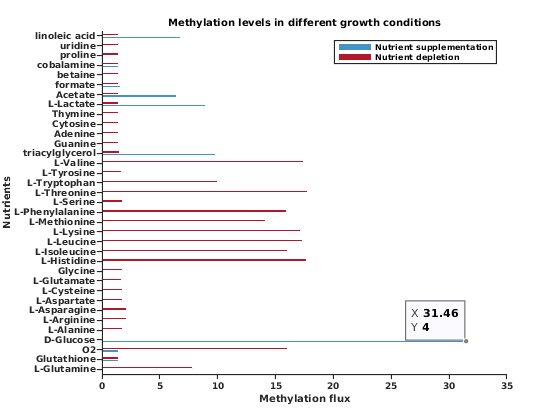

labels(2) = {'Glutathione'};
idx = [1:4, 20:50];

figure;
h = barh([ptm_1(idx, 1), ptm_2(idx, 1)],...
    'edgecolor', 'w');
h(1).FaceColor = '#4393c3';
h(2).FaceColor = '#b2182b';
title('Methylation levels in different growth conditions', ...
      'fontweight', 'bold')
set(gca,'ytick', ...
    [1:length(mediareactions1(idx))], ...
    'yticklabel', labels(idx), ...
    'fontsize', 8, ...
    'fontweight', 'bold', ...
    'TickDir', 'out', ...
    'box', 'off', ...
    'linewidth', 1, ...
    'color', 'white');
xlabel('Methylation flux'); ylabel('Nutrients');
legend({'Nutrient supplementation', 'Nutrient depletion'});

## Heatmap of the data

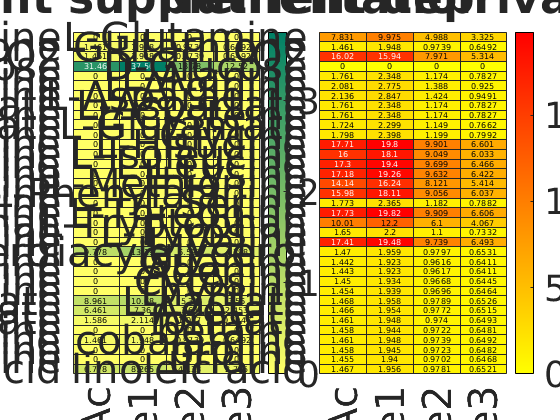

figure;
subplot(1, 2, 1)
h = heatmap(ptm_1(idx, :), ...
            'Colormap', flipud(summer), ...
            'FontSize', 30);
title('Nutrient supplementation')
set(gca, ...
    'YData', labels(idx), ...
    'XData', {'Ac', 'Me1', 'Me2', 'Me3'})
subplot(1, 2, 2)
h = heatmap(ptm_2(idx, :), ...
            'Colormap', flipud(autumn), ...
            'FontSize', 30);
title('Nutrient deprivation')
set(gca, ...
    'YData', labels(idx), ...
    'XData', {'Ac', 'Me1', 'Me2', 'Me3'})